clc;
clear all;
close all;
T = 500

T = 500

L = 100

L = 100

n = 10

n = 10

m = 1

m = 1


% signal duration corresponds to the frame rate
% so dt = 1/35 is fixed

## Signal Generator

% random signal
% U = rand(1,T)>0.8

% spaced signal
th = 0.4

th = 0.4000

r = 452134

r = 452134

avg = 5

avg = 5

U=[];
for i = 1:T
    rng(r+i)
    u = double(rand(1)>th);
    U = [U,u];
    if i <= avg
        U(:,end) = 0;
    elseif U(:,end-1) == 0 && mean(U(:,end-4:end)) > 1/avg
        U(:,end) = 0;
    end

end



H = hankel(U)

H =      0     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     1     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     1     1     1     1     0     0     0     0     1
     0     0     0     0     0     1     1     1     1     0     0     0     0     1     0   

Hu = double(H(1:n+L,:))

Hu =      0     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     1     1     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     1     1     1     1     0     0     0     0     1
     0     0     0     0     0     1     1     1     1     0     0     0     0     1     0  

rank(Hu)

ans = 110

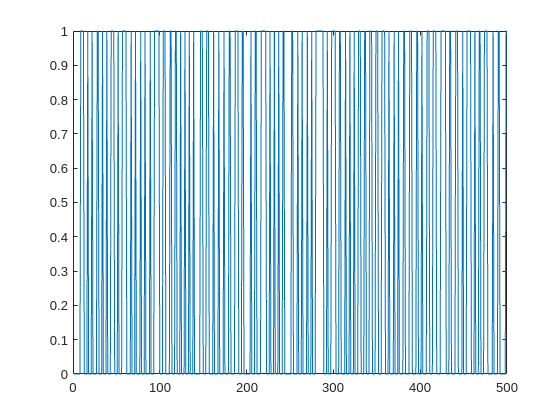

figure()
plot(U)